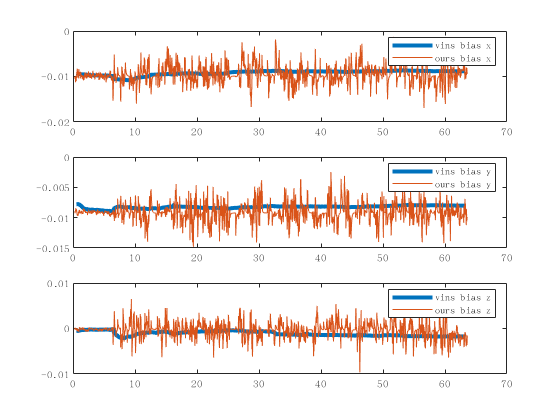

bais_vins = load('/media/qzj/Software/code/catkin_ws/src/ORB-SLAM3/data/imuBiasVINS01.txt');
bais_orb = load('/media/qzj/Software/code/catkin_ws/src/ORB-SLAM3/data/imuBiasORB01.txt');
bais_vins(:,1) = bais_vins(:,1) -bais_vins(1,1);
bais_orb(:,1) = bais_orb(:,1) -bais_orb(1,1);
subplot(311);
plot(bais_vins(15:end,1),bais_vins(15:end,2),'LineWidth',3)
hold on
plot(bais_orb(15:end,1),bais_orb(15:end,2))
legend('vins bias x','ours bias x')
subplot(312);
plot(bais_vins(15:end,1),bais_vins(15:end,3),'LineWidth',3)
hold on
plot(bais_orb(15:end,1),bais_orb(15:end,3))
legend('vins bias y','ours bias y')
subplot(313);
plot(bais_vins(15:end,1),bais_vins(15:end,4),'LineWidth',3)
hold on
plot(bais_orb(15:end,1),bais_orb(15:end,4))
legend('vins bias z','ours bias z')